## Método de Newton-Raphson para optimización

Con el uso de segunda derivada dentro de la función, podemos obtener un punto crítico de la función

clear; clf;
f = @(x) -12-21.*x + 18.*x.^2 - 2.75.*x.^3;
fs = sym(f)

$$fs = -\frac{11\,x^{3}}{4}+18\,x^{2}-21\,x-12$$

x = roots([-2.75 18 -21 -12])

x =     4.7403
    2.2198
   -0.4147


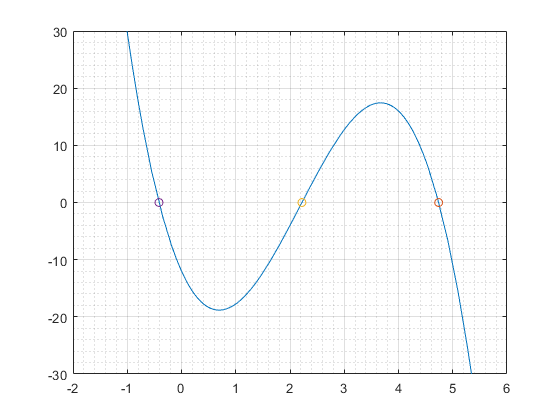

fplot(f);
grid on; grid minor; hold on;
axis([-2 6 -30 30]);
plot(x,0,'o'); hold off;

[raiz, iteraciones, fx1] = NewtonRaphsonOptimizado(f, 3)

raiz = 3.6701

iteraciones = 6

fx1 = 0

function [x, i, df1x] = NewtonRaphsonOptimizado(f,x)
    max_iter = 53;
    tol = eps();
    
    fsym = sym(f);
    dfs1 = diff(fsym,1);
    dfs2 = diff(fsym,2);
    df1 = matlabFunction(dfs1);
    df2 = matlabFunction(dfs2);
     
    i = 0;
    cond = true;
    while cond
        xn = x;
        df1x = df1(x);
        ddx = -df1x/df2(x);
        x = xn + ddx;
        
        i = i + 1;
        cond = abs(ddx/x) > tol && i < max_iter;
    end
end